n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 10; 
%%%%%%%%%%%%
sep = 6;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);

p_start = 10;
p_end = 10000;
n_grid = 20;
p_vec =  [round(linspace(p_start, p_end, n_grid))];
n_rep = 100;

n_pararell = 10;
n_p_chunk = n_grid/n_pararell;
p_vec_chunk = {};
clustering_acc_mat_chunk = {};

for i = 1:n_pararell
    p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : (i*n_p_chunk) );
    clustering_acc_mat_chunk{i} = repmat( repelem(0, n_p_chunk ), n_rep, 1 );
end



tic
% parallel for loop
parfor w = 1 : n_pararell
    for i = 1:length(p_vec_chunk{w})
    p = p_vec_chunk{w}(i)
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
        % iterate
 
        clustering_acc_mat_chunk{w}(j, i) = iterative_kmeans(x, sigma, K, p, n_iter, rounding, n, cluster_true);
    end
end
end

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-0

toc

Elapsed time is 7102.147333 seconds.


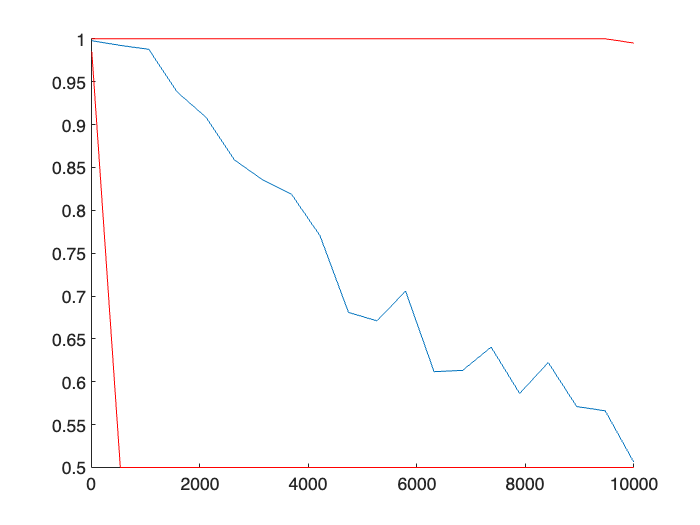

clustering_acc_mat = [];
for i = 1:n_pararell
    clustering_acc_mat = [clustering_acc_mat, clustering_acc_mat_chunk{i}];
    x = p_vec;                     
    y = mean(clustering_acc_mat,1);
    y_max = max(clustering_acc_mat);
    y_min = min(clustering_acc_mat);
end

figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off